2. Considere  una  señal  portadora  de  20Hz  con  una  señal  moduladora  de  1  bit  por segundo con modulación ASK por código de línea unipolar NRZ y otro que usted seleccione.  Obtenga  la  DEP  de  la  señal  modulada  cuando  el  pulso  del  filtro formador  es  un  pulso  rectangular  y  cuando  es  un  coseno  alzado  con  ancho  de banda de exceso =.5, de la manera:

### Señal portadora de 20HZ

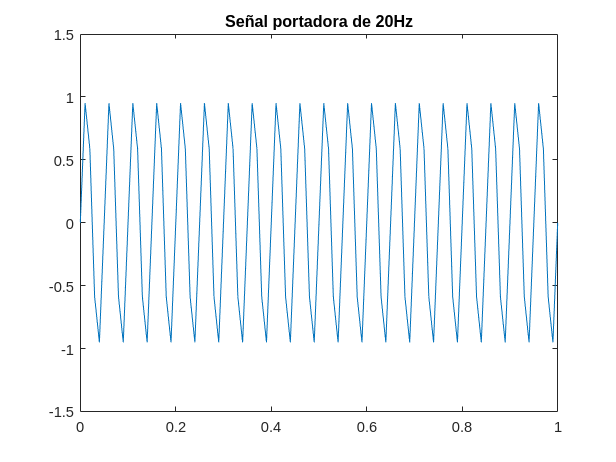

clear all; close all;
fs     = 100;
time = 0:1/fs:8-1/fs;
fport = 20; % 20 Hz
portadora = sin(2*pi*time*fport);
plot(time,portadora);
axis([0 1 -1.5 1.5]);
title('Señal portadora de 20Hz');

### Generacion de bits aleatorios

N    = 8; % number of bits to be transmited
Tb   = 1; % tiempo de bit en segundos
bits = round(rand(1,N))% input bit stream

bits =      0     0     1     1     0     1     1     1


digit = []; 
for n = 1:1:N
    if bits(n) == 1
       sig = ones(1,fs);
    else bits(n) == 0
        sig = zeros(1,fs);
    end
     digit = [digit sig];
end

ans = logical
   1


ans = logical
   1


ans = logical
   1


t1 = Tb/fs:Tb/fs:fs*N*(Tb/fs);   % Time period for bits
figure('Name','Line Coding Schemes','NumberTitle','off');
subplot(3,1,1);
plot(t1,digit,'LineWidth',2.5);
grid on;
axis([0 Tb*N -0.5 1.5]);
xlabel('Time(Sec)');
ylabel('Amplitude(Volts)');
title('Digital Input Signal');

### Codigo de linea NRZ unipolar 

clc;
for i = 0:N-1
  if bits(i+1) == 1
    UNRZ(i*fs+1:(i+1)*fs) = 1;
  else
    UNRZ(i*fs+1:(i+1)*fs) = 0;
  end
end

subplot(3,1,2)
plot(t1,UNRZ,'LineWidth',2.5); grid on;
axis([0 Tb*N -0.5 1.5]);
xlabel('Time(Sec)');
ylabel('Amplitude(Volts)');
title(['Unipolar NRZ']);

### Codigo de linea Manchester

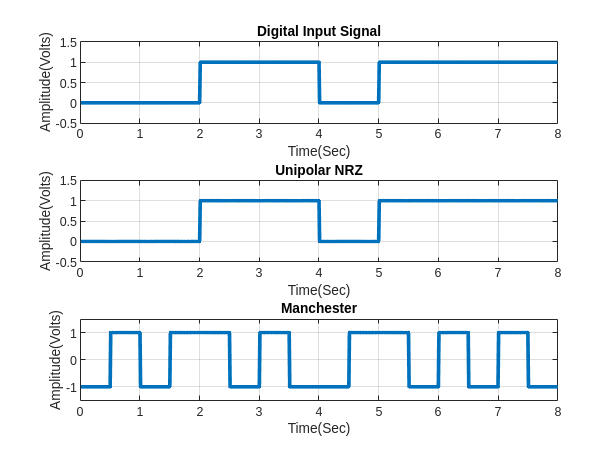

for i = 0:N-1
  if bits(i+1) == 1
    Manchester(i*fs+1:(i+0.5)*fs) = 1;
    Manchester((i+0.5)*fs+1:(i+1)*fs) = -1;clc;
  else
    Manchester(i*fs+1:(i+0.5)*fs) = -1;
    Manchester((i+0.5)*fs+1:(i+1)*fs) = 1;
  end
end
subplot(3,1,3)
plot(t1,Manchester,'LineWidth',2.5); grid on;
axis([0 Tb*N -1.5 1.5]);
xlabel('Time(Sec)');
ylabel('Amplitude(Volts)');
title(['Manchester']);

### Moduacion ASK

clc;
ASK_UNRZ =  portadora.*UNRZ;
ASK_Manchester = portadora.*Manchester;

#### DEP Filtro formador  es  un  pulso  rectangular 

#### Graficas modulacion ASK

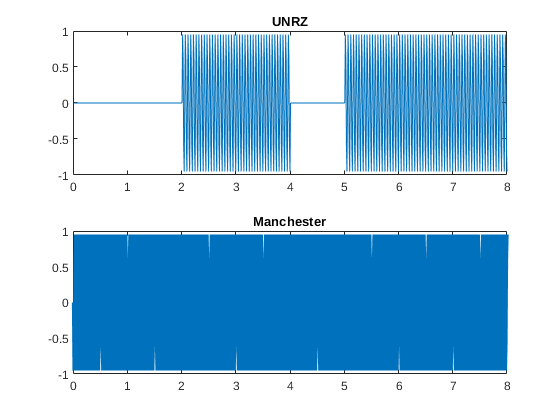

figure(3);
subplot(2,1,1,'LineWidth',2.5);grid on;
plot(t1,ASK_UNRZ)
title(['UNRZ']);
subplot(2,1,2)
plot(t1,ASK_Manchester,'LineWidth',2.5);grid on;
title(['Manchester']);

#### DEP con pulso formador rectangular

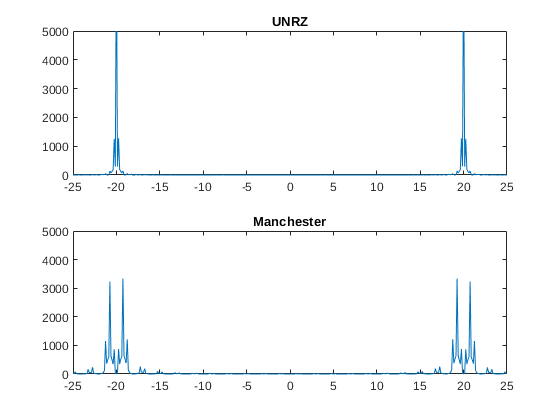

ASK_UNRZ_DEP = abs(ttof(ASK_UNRZ)).^2/N;
ASK_Manchester_DEP = abs(ttof(ASK_Manchester)).^2/N;
freq = -fs/2:1/8:fs/2-1/8;
figure(4)
subplot(2,1,1)
plot(freq,ASK_UNRZ_DEP)
axis([-25 25 0 5000]);
title(['UNRZ']);
subplot(2,1,2)
plot(freq,ASK_Manchester_DEP)
axis([-25 25 0 5000]);
title(['Manchester']);

### DEP con pulso formador rised cosine


% -Se definen los valores de los pulsos
frcosine=zeros(1,length(t1));
temp = rcosdesign(0.5,3,fs);
frcosine(1:300) = temp(1:end-1);
%—— Rcosine conv -----
ASK_rcos=convrec(ASK_UNRZ,frcosine);

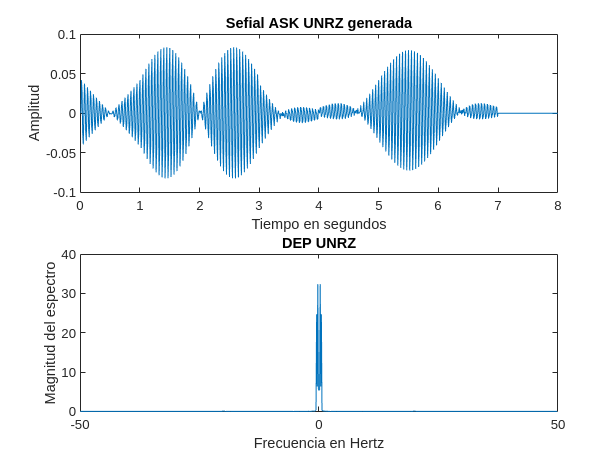

ASK_UNRZ_smooth   = ASK_rcos.* portadora;
figure(8);
subplot(2,1,1), plot(t1,ASK_UNRZ_smooth);
xlabel('Tiempo en segundos');
ylabel('Amplitud');
title('Sefial ASK UNRZ generada');
ASK_UNRZ_smooth_f=abs(ttof(ASK_UNRZ_smooth))*.01;
subplot(2,1,2), plot(freq,ASK_UNRZ_smooth_f); 
xlabel('Frecuencia en Hertz'); 
ylabel('Magnitud del espectro'); 
 plot(t1,ASK_rcos); 
xlabel('Tiempo en segundos'); 
title('Serial moduladora a un segundo por bit'); 
ylabel('Amplitud'); 
modenfrec=abs(ttof(ASK_rcos)).^2/N;
subplot(2,1,2), plot(freq,modenfrec);
title('DEP UNRZ'); 
xlabel('Frecuencia en Hertz'); 
ylabel('Magnitud del espectro'); 

With manchester 

Manchester_rcos=convrec(Manchester,frcosine);

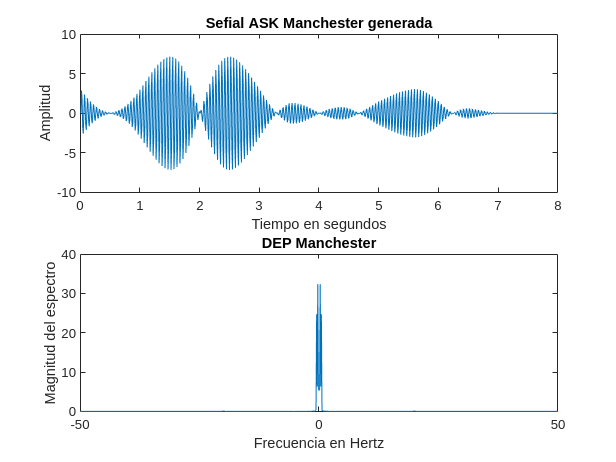

Manchester_smooth  = Manchester_rcos.* portadora;
figure(9);

subplot(2,1,1), plot(t1,Manchester_smooth);
xlabel('Tiempo en segundos');
ylabel('Amplitud');
title('Sefial ASK Manchester generada');
Manchester_smooth_f=abs(ttof(Manchester_smooth))*.01;
subplot(2,1,2), plot(freq,Manchester_smooth_f); 
xlabel('Frecuencia en Hertz'); 
ylabel('Magnitud del espectro'); 
 plot(t1,ASK_rcos); 
xlabel('Tiempo en segundos'); 
title('Serial moduladora a un segundo por bit'); 
ylabel('Amplitud'); 
modenfrec=abs(ttof(ASK_rcos)).^2/N;
subplot(2,1,2), plot(freq,modenfrec);
title('DEP Manchester'); 
xlabel('Frecuencia en Hertz'); 
ylabel('Magnitud del espectro'); 